# Семинар 1. Базовые типы МАТЛАБ

- Типы double, logical

- Массивы, размерность, индексирование

#### Тип double - основной числовой тип 

Число с плавающей точкой x , хранится в виде:


$$x=(-1)^{s} \cdot(1+f)\cdot2^e$$


где:

- *s* определяет знак

- *f* - мантисса, для которой 0 ≤ *f* < 1.

- *e* - экспонента.

*s*, *f*, и *e* определяются конечным числом бит в памяти

Тип **double **требует 64 бита, которые распределены, как показано в таблице.

class(1) % функция class(...) возвращает тип объекта

ans = 'double'

class(1.0)

ans = 'double'

1==1.0 % эквивалентно, то есть даже те числа, которые пишутся как целые матлабом

ans = logical
   1


% воспринимаются как числа с плавающей точкой (если никакого типа не
% задано)
1e3 % можно записывать в e-notation

ans = 1000


 num2hex(1) % представляет число в шестнадцатеричной системе 

ans = '3ff0000000000000'

num2hex(1.0)

ans = '3ff0000000000000'

num2hex(1.0000000000000001)

ans = '3ff0000000000000'

num2hex(1.0000000000000002)

ans = '3ff0000000000001'

num2hex(realmin)

ans = '0010000000000000'

1.0000000000000001==1

ans = logical
   1


1.0000000000000002==1

ans = logical
   0



eps % минимальная разница между числами с плавающей точкой

ans = 2.2204e-16

realmin % минимальное значение 

ans = 2.2251e-308

realmax

ans = 1.7977e+308

a = realmax

a = 1.7977e+308

b = a+eps

b = 1.7977e+308

a-b

ans = 0

Особые числа inf и NaN

num2hex(Inf)

ans = '7ff0000000000000'

num2hex(NaN)

ans = 'fff8000000000000'

%NaN==NaN
Inf==Inf

ans = logical
   1


bit_nan = num2hex(NaN)

bit_nan = 'fff8000000000000'

bit_nan(end)='f'

bit_nan = 'fff800000000000f'

hex2num(bit_nan)

ans = NaN

fit_inf = num2hex(inf)

fit_inf = '7ff0000000000000'

fit_inf(1)='7'

fit_inf = '7ff0000000000000'

hex2num(fit_inf)

ans = Inf

### Тип logial  - основной логический тип `logical - 2 бита`

a = true

a = logical
   1


b= false

b = logical
   0


#### Другие типы (об их существовании можно не знать до того как понадобится писать данные в бинарные файлы или работать с портами в бинарном режиме):

- `single`  - 32-бита

- `int8`, `int16`, `int32`, `int64` 

- `uint8`, `uint16`, `uint32`, `uint64` 

- `char - 8 бит`

## Массивы: вектора, матрицы и многомерные массивы  чисел и логических элементов 

Массив  - конструкция для хранения данных одного типа. 

Заполнения массивов вручную

clearvars % удаляет все переменные из памяти
a_row = [1,2,3,4] %  - строка

a_row =      1     2     3     4


a_col = [1;2;3;4] %  - столбец

a_col =      1
     2
     3
     4


a_row2 = [1 2 3 4]; %  - строка
a_lin = linspace(1,10,100); % фиксировано количество элементов (возвращает строку)
a_range = 1:0.01:100; % фиксированный шаг
a_range2 = 1:10; % если шаг не указанЮ будет единица
a_mat = [1,2,3,4;5,6,7,8] % матрица 2х4

a_mat =      1     2     3     4
     5     6     7     8


Размерность массива

clearvars
a_scalar = 5 % массив размером (1,1)

a_scalar = 5

a_row = [1,2,3,4]; %  - строка
a_col = [1;2;3;4]; %  - столбец
a_mat = [1,2,3,4;5,6,7,8]; % матрица 2х4
size(a_row)

ans =      1     4


size(a_col)

ans =      4     1


numel(a_mat)

ans = 8

size(a_mat)

ans =      2     4


size(a_mat,2) % количество столбцов

ans = 4

ndims(a_mat) % количество размерностей больших единицы

ans = 2

empty_mat = []


empty_mat =

     []



size(empty_mat)

ans =      0     0


whos empty_mat % функция whos выдает информацию о переменных 

  Name           Size            Bytes  Class     Attributes

  empty_mat      0x0                 0  double              



### Индексирование

Прямое индексирование. 

clearvars
a_rand = rand(10); % функция создает массив случайных чисел размером 10х10
a_rand(1,1) % (строка,столбец) декартово индексирование

ans = 0.1067

a_rand(100) % линейное (MATLAB - COLUMN ORIENTED LANGUAGE!)

ans = 0.4357

a_scalar = 5 % массив размером (1,1)

a_scalar = 5

a_scalar(1) % ВСЕ МАССИВ!

ans = 5

Индексирование при помощи "сахара": символы "**:**" и "**end**"

clearvars
a_rand = rand(10); 
col1 = a_rand(:,2)% возвращает второй толбец

col1 =     0.5949
    0.2622
    0.6028
    0.7112
    0.2217
    0.1174
    0.2967
    0.3188
    0.4242
    0.5079


row1 = a_rand(1,:)% возвращает первую строку

row1 =     0.3111    0.5949    0.0855    0.9631    0.0377    0.1068    0.0305    0.1829    0.0596    0.6596


a_mat = [1,2,3,4;5,6,7,8]

a_mat =      1     2     3     4
     5     6     7     8


col = a_mat(:) % превращает матрицу в вектор-колонку

col =      1
     5
     2
     6
     3
     7
     4
     8


submat = a_mat(2:end,:)

submat =      5     6     7     8


Если при работе программы происходит изменение размера массива, то это сильно замедляет вычисления, чтобы этого избежать нужно резервировать память

Способы резервировать память 

clearvars
a_zeros = zeros(10);
a_ones = ones(10,'double');
a_nan = NaN(10);% not-a-number
a_zeros5x5x10 = zeros([5 5 10]);
i_complex = 1i; % мнимая единица
a_complex = zeros(10,'like',i_complex); % удобно, когда в процессе работы не известно какого типа будут данные  (пример - в функциях)
a_uint8 = zeros(10,'uint8');% можно указывать тип в явном виде
a_logical = false(10);% матрица 10х10 false
a_rand = rand(10);% матрица 10х10

BATTLE$\dagger$ - соревнование по скорости

timeit() - позволяет замерить время работы функции без входных аргументов

значок "@" - создает указатель на функцию (что это такое обсудим когда-нибудь потом), в данном случае нужен чтобы превратить функцию с аргументом в функцию без аргумента

BATTLE$\dagger$ Сравнение скорости заполнения матриц

clearvars
disp("Заполнение NaN'ами:")

Заполнение NaN'ами:


t1 = timeit(@()NaN(1000)) % заполнение NaN

t1 = 0.0039

disp("Заполнение нулями:")

Заполнение нулями:


t2 = timeit(@()zeros(1000)) % заполнение нулями

t2 = 1.1484e-05

disp("Заполнение inf'ами:")

Заполнение inf'ами:


t3 = timeit(@()inf(1000)) % заполнение инфами

t3 = 0.0023

disp("Заполнение единицами:")

Заполнение единицами:


t4 = timeit(@()ones(1000)) % заполнение единицами

t4 = 0.0022

BATTLE$\dagger$Влияние преаллокации памяти на скорость вычислений

clearvars
disp("заполнение без преаллокации памяти:")

заполнение без преаллокации памяти:


timeit(@fill_by_column_no_memalloc) % no memory allocation

ans = 0.3196

disp("заполнение с преаллокацией памяти:")

заполнение с преаллокацией памяти:


timeit(@fill_by_column) % with memory allocation

ans = 0.0999

Заполнение матрицы из массива

clearvars
A = zeros(10);% memory allocation
a = linspace(1,100,100);
A(:) = a

A =      1    11    21    31    41    51    61    71    81    91
     2    12    22    32    42    52    62    72    82    92
     3    13    23    33    43    53    63    73    83    93
     4    14    24    34    44    54    64    74    84    94
     5    15    25    35    45    55    65    75    85    95
     6    16    26    36    46    56    66    76    86    96
     7    17    27    37    47    57    67    77    87    97
     8    18    28    38    48    58    68    78    88    98
     9    19    29    39    49    59    69    79    89    99
    10    20    30    40    50    60    70    80    90   100


Индексирование при помощи массива

clearvars
a_col = [1;2;3;4]; %  - столбец
r_index = randi(4,100);% функция возвращает 100 случайных целых числа в интервале от 1 до 4
a_permuted = a_col(r_index) % матрица из случаных перестановок элементов массива a_col

a_permuted =      4     2     3     1     4     3     1     1     2     2     2     1     3     4     4     4     1     3     4     2     1     4     1     4     2     4     4     3     1     4     1     1     4     4     3     3     1     4     4     1     1     1     2     4     4     1     1     1     3     2
     2     2     3     2     2     2     2     1     1     1     2     1     2     3     3     3     4     3     4     4     4     2     4     4     4     4     2     1     2     4     4     3     3     3     3     1     2     2     4     1     4     3     3     4     1     3     3     3     2     2
     1     2     1     1     1     2     1     1     2     4     2     3     3     1     2     3     3     3     4     4     1     2     1     1     1     3     2     1     1     2     1     4     1     1     1     3     1     4     3     3     4     3     1     4     1     2     1     1     2     4
     2     4     3     3     1     2     3     2     2     4     4     4     1     1

Пример  - вытаскивание диагонали:

clearvars
a_rand = rand(10); % генерим матрицу
col_size = size(a_rand,1); % число элементов в одном столбце
a_diagonal = a_rand(1:col_size+1:end); % индексирование при помощи диапазона с шагом

Удаление элемента при помощи индексирования

clearvars
a = 1:5;
a(2) = [] % изменяет матрицу in-place!
a(2:4)=[]; %???

Индексирование многомерных массивов

a_rand_3d = rand([10,10,10]);% трехмерная матрица 
a_rand_3d(2,3,5) % элемент второй строки третьего столбца пятой страницы
size(a_rand_3d(:,2,:))
size(a_rand_3d(:))

Создание массива при индексировании:

clearvars 
a_mat(10,10)=10 

BATTLE$\dagger$Преаллокация памяти путем обратного индексирования:

disp("заполнение без преаллокации памяти:")

заполнение без преаллокации памяти:


timeit(@fill_by_column_no_memalloc) % no memory allocation

ans = 0.3132

disp("заполнение с преаллокацией памяти:")

заполнение с преаллокацией памяти:


timeit(@fill_by_column) % with memory allocation

ans = 0.1061

disp("заполнение с преаллокацией памяти путем обратного индексирования:")

заполнение с преаллокацией памяти путем обратного индексирования:


timeit(@fill_by_column_reverse_order)

ans = 0.1485

Таким образом: A(10:-1:1)=0, быстрее, чем A(1:1:10), так как в первом случае, преаллокация происходит один раз на первой итерации!

Но A = zeros([10,1]), все равно быстрее

Конкатенация матриц и векторов

clearvars
a = 1:5 % создаем вектор-строку

a =      1     2     3     4     5


b = [a,10] % [.,.]  функции horzcat

b =      1     2     3     4     5    10


b2 = horzcat(a,10)

b2 =      1     2     3     4     5    10


c = [a,a]

c =      1     2     3     4     5     1     2     3     4     5


v_col = [a(:),a(:)]

v_col =      1     1
     2     2
     3     3
     4     4
     5     5


v_row = [a(:);a(:)]% [.;.]  функции vertcat

v_row =      1
     2
     3
     4
     5
     1
     2
     3
     4
     5


v_row2 = [a;a]

v_row2 =      1     2     3     4     5
     1     2     3     4     5


v_mat = [rand([5 2]),rand([5 2])]

v_mat =     0.3619    0.1597    0.3939    0.3177
    0.9521    0.5718    0.3369    0.9927
    0.9322    0.5929    0.1290    0.7236
    0.9581    0.6986    0.0869    0.5721
    0.2065    0.3058    0.5489    0.7172


v_mat2 = [rand([5 2]);rand([5 2])]

v_mat2 =     0.9766    0.0480
    0.4270    0.3593
    0.9130    0.2958
    0.8973    0.6291
    0.8352    0.1362
    0.3740    0.6051
    0.8648    0.2442
    0.2503    0.4382
    0.0295    0.7351
    0.9994    0.5580


### Символьные типы  char и string

clearvars
s_char = 'asfzassgfagag'; % ведут себя как массивы символов
s_string = "asfzassgfagag";% ведут себя как массивы групп символов
s_char(10)
%s_string(10)
s_char_pen = char(10000);
s_char_big = char(rand([1 10000]));
s_string_big = string(s_char_big);
onechar = 'a';
onestring = "a";
whos one*
whos s_*
a_range_char = 'a':'z';
a_range_string = arrayfun(@(x)string(x),a_range_char);% создаем массив строк
"a"<="b"
'a'<='b'
s_char<s_char

Пустые массивы

clearvars
empty_char = ''
fake_empty_string = ""
whos empty_char
whos fake_empty_string
real_empty_string = strings(0,0)
whos real_empty_string

BATTLE$\dagger$ Что быстрее строки или массивы символов?

[r_str,r_ch] = gen_random_string(1e6)% функция генерит случаную последовательность 1e5 символов

r_str = "mnmjjyamxtdgdtgjeetngjgdbmhgixkerabvefcuyfweugsdkmedmmrximvhwtaeudbcysngctqmvqkphajpjdcartjkqyrhtsiemvsxtramrtcfpbkialtnivckqcmjyndyloumueyrwvbiscxbifmbjwuswmfgmsgdvonkjxxjrlnmvyqgqnlesfqnwvavvinghydrmytuscrucdbxxfvghammwasbmtvjsdntpwowajuayvlhgkhuebydtwmmehqtkpvtyhiheedvrrapwkcgefnxyadkbcrrbysqfuoanmtqxouomhcfbqnbekretgjvxfumljreptkdoojhfvcqesmactihqjnjosfdbwlybkoewriclqwogyergltyquoglmvammcfynbwmmvmcoidmrtqljhgyooyqekqrasmvbqbfjncouqsgulepglpewhxwjgagmaahekxqgxormpgijrhpphayxfsvcxdjuxytupbyjasnbukctjyvgbrnwvloejkjatxxohxqthpdlvagrivbkdtkigehjhuuttionhikiavnmkrllqlnrislptpmksgiydavsvrdhbdviygbtvhlmuoaawliwgcxtrjlngpxpwtmflngaonvlchnufqqgqpfamsuxtglkwtagqnbkdraqcaihsaictuydhjyusyoqvrytvuggwfstbpeuelwqjdecgiavdxrmaxfmjlhwuqgxkmeruvqdryoyesqkhscyjlqvynuvwverqjsoffryprerimrhvcnfeqfacfahylelxivpnlcjclgtibwyupqfyvuiltqnveyuhrhugbndejlcohbpfelaabydcxeiphxeaqctvpysfjsgqslgjoncgsudsuddmukltnfofrrtfjvfdxvwwxdaacaapefblhkikwvxljjfydhosikjhnfrcirfwdjmcmmndfphfhnraqtwkpvplehnfirxunxupstuf

r_ch = 'mnmjjyamxtdgdtgjeetngjgdbmhgixkerabvefcuyfweugsdkmedmmrximvhwtaeudbcysngctqmvqkphajpjdcartjkqyrhtsiemvsxtramrtcfpbkialtnivckqcmjyndyloumueyrwvbiscxbifmbjwuswmfgmsgdvonkjxxjrlnmvyqgqnlesfqnwvavvinghydrmytuscrucdbxxfvghammwasbmtvjsdntpwowajuayvlhgkhuebydtwmmehqtkpvtyhiheedvrrapwkcgefnxyadkbcrrbysqfuoanmtqxouomhcfbqnbekretgjvxfumljreptkdoojhfvcqesmactihqjnjosfdbwlybkoewriclqwogyergltyquoglmvammcfynbwmmvmcoidmrtqljhgyooyqekqrasmvbqbfjncouqsgulepglpewhxwjgagmaahekxqgxormpgijrhpphayxfsvcxdjuxytupbyjasnbukctjyvgbrnwvloejkjatxxohxqthpdlvagrivbkdtkigehjhuuttionhikiavnmkrllqlnrislptpmksgiydavsvrdhbdviygbtvhlmuoaawliwgcxtrjlngpxpwtmflngaonvlchnufqqgqpfamsuxtglkwtagqnbkdraqcaihsaictuydhjyusyoqvrytvuggwfstbpeuelwqjdecgiavdxrmaxfmjlhwuqgxkmeruvqdryoyesqkhscyjlqvynuvwverqjsoffryprerimrhvcnfeqfacfahylelxivpnlcjclgtibwyupqfyvuiltqnveyuhrhugbndejlcohbpfelaabydcxeiphxeaqctvpysfjsgqslgjoncgsudsuddmukltnfofrrtfjvfdxvwwxdaacaapefblhkikwvxljjfydhosikjhnfrcirfwdjmcmmndfphfhnraqtwkpvplehnfirxunxupstufl

disp("Поиск и замена паттерна в строке:")

Поиск и замена паттерна в строке:


timeit(@()replace(r_str,"a","I"))

ans = 0.0031

disp("Поиск и замена паттерна в массиве символов:")

Поиск и замена паттерна в массиве символов:


timeit(@()replace(r_ch,'a','I'))

ans = 0.0058

Конкатенация символьных типов

clearvars
s_char = 'a':'z'
[s_char,s_char]
[s_char;s_char]
s_string = arrayfun(@(x)string(x),s_char);% создаем массив строк
[s_string;s_string]

#### Базовые операции над массивами

Операции сравнения и логическое индексирование

clearvars
a = 1:10 % вектор-строка
% сравнение массива и скаляра
flag1 = a>3 % логический массив
sum(flag1) % самый быстрый способ посчитать количество элементов массива, удовлетворящих условию
b = randi(10,[1 10]) % вектор-строка случаных элементов
flag2 = a==b % проверяет элементы 
A_mat = rand(10)
flag_mat = A_mat>0.5
sum(flag_mat,"all") % суммирование по всем элементам
A_mat(flag_mat) % возвращает вектор-столбец
col_vec = randi(10,[5,1])
row_vec = randi(10,[1,3])
flag_col_row = col_vec>row_vec % ???
flag_row_col = row_vec>col_vec % ???

Как выбрать из массива элементы, удовлетворяющие неравенству:

clearvars
 a = rand(10,1)
 flag1 = a>0.8
 flag2 = a<0.2
 % логический плюс
 flag_union = flag1 | flag2
 % 
 flag_intersection = a>=0.2 & a<=0.5
 a(flag_union) % элементы, которые либо <0.2, либо >0.8
 a(flag_intersection) % элементы лежащие внутри [0.2,0.8]

 % эквивалентно неравенству 


# Выводы семинара 1.

- Базовый матлаб - double  - число с плавающей точкой

- Базовый объект  - массив.  

- Массивы поддерживают два основных метода работы a= M(i) - получить элемент массива (get_index), M(i)=a - задать элемент массива (set_index)

- Массивы поддерживают линейное индексирование (один индекс) и декартово (число индексов равно размерности массива).

- Можно индексировать при помощи массивов индексов и при помощи логических массивов

- Метод set_index позволяет изменять размер массива в процессе выполнения программы, однако это медленно, поэтому нужно делать преаллокацию

- Самый быстрый способ преаллокации - функция zeros(), можно делать преаллокацию обратным индексированием

- Есть два базовых типа символьных объектов: 'char' - массив символов и "string" - массив групп символов, первый ест меньше памяти, второй немного быстрее

# Семинар 2. Арифметические операции над массивами и инструменты языка для управления потоком выполнения программы 

- Арифметика

- if-else

- Циклы

## Арифметика 

Арифметику удобней показывать на символьных переменных (symbolic toolbox), символьные массивы ведут себя также как численные 

clearvars
type = "sym"

type = "sym"

switch type
    case "sym"
        a_col = sym('a',[3 1])
        b_row = sym('b',[1 4])
        M3x4 = sym('m',[3,4])
        W3x4 = sym('w',[3,4])
        B3x3 = sym('B',[3 3])
    case "num"
        a_col = rand([3 1])
        b_row = rand([1 4])
        M3x4 = rand([3,4])
        W3x4 = rand([3,4])
        B3x3 = rand([3 3])
end

$$a\_col = \left(\begin{array}{c} a_{1}\\ a_{2}\\ a_{3} \end{array}\right)$$

$$b\_row = \left(\begin{array}{cccc} b_{1} & b_{2} & b_{3} & b_{4} \end{array}\right)$$

$$M3x4 = \left(\begin{array}{cccc} m_{1,1} & m_{1,2} & m_{1,3} & m_{1,4}\\ m_{2,1} & m_{2,2} & m_{2,3} & m_{2,4}\\ m_{3,1} & m_{3,2} & m_{3,3} & m_{3,4} \end{array}\right)$$

$$W3x4 = \left(\begin{array}{cccc} w_{1,1} & w_{1,2} & w_{1,3} & w_{1,4}\\ w_{2,1} & w_{2,2} & w_{2,3} & w_{2,4}\\ w_{3,1} & w_{3,2} & w_{3,3} & w_{3,4} \end{array}\right)$$

$$B3x3 = \left(\begin{array}{ccc} B_{1,1} & B_{1,2} & B_{1,3}\\ B_{2,1} & B_{2,2} & B_{2,3}\\ B_{3,1} & B_{3,2} & B_{3,3} \end{array}\right)$$

% СЛОЖЕНИЕ
a_col + a_col

$$ans = \left(\begin{array}{c} 2\,a_{1}\\ 2\,a_{2}\\ 2\,a_{3} \end{array}\right)$$

plus(a_col,a_col)

$$ans = \left(\begin{array}{c} 2\,a_{1}\\ 2\,a_{2}\\ 2\,a_{3} \end{array}\right)$$

a_col + b_row

$$ans = \left(\begin{array}{cccc} a_{1}+b_{1} & a_{1}+b_{2} & a_{1}+b_{3} & a_{1}+b_{4}\\ a_{2}+b_{1} & a_{2}+b_{2} & a_{2}+b_{3} & a_{2}+b_{4}\\ a_{3}+b_{1} & a_{3}+b_{2} & a_{3}+b_{3} & a_{3}+b_{4} \end{array}\right)$$

a_col.^b_row

$$ans = \left(\begin{array}{cccc} {a_{1}}^{b_{1}} & {a_{1}}^{b_{2}} & {a_{1}}^{b_{3}} & {a_{1}}^{b_{4}}\\ {a_{2}}^{b_{1}} & {a_{2}}^{b_{2}} & {a_{2}}^{b_{3}} & {a_{2}}^{b_{4}}\\ {a_{3}}^{b_{1}} & {a_{3}}^{b_{2}} & {a_{3}}^{b_{3}} & {a_{3}}^{b_{4}} \end{array}\right)$$

M3x4 + W3x4

$$ans = \left(\begin{array}{cccc} m_{1,1}+w_{1,1} & m_{1,2}+w_{1,2} & m_{1,3}+w_{1,3} & m_{1,4}+w_{1,4}\\ m_{2,1}+w_{2,1} & m_{2,2}+w_{2,2} & m_{2,3}+w_{2,3} & m_{2,4}+w_{2,4}\\ m_{3,1}+w_{3,1} & m_{3,2}+w_{3,2} & m_{3,3}+w_{3,3} & m_{3,4}+w_{3,4} \end{array}\right)$$

M3x4 + 3

$$ans = \left(\begin{array}{cccc} m_{1,1}+3 & m_{1,2}+3 & m_{1,3}+3 & m_{1,4}+3\\ m_{2,1}+3 & m_{2,2}+3 & m_{2,3}+3 & m_{2,4}+3\\ m_{3,1}+3 & m_{3,2}+3 & m_{3,3}+3 & m_{3,4}+3 \end{array}\right)$$

M3x4 + a_col

$$ans = \left(\begin{array}{cccc} a_{1}+m_{1,1} & a_{1}+m_{1,2} & a_{1}+m_{1,3} & a_{1}+m_{1,4}\\ a_{2}+m_{2,1} & a_{2}+m_{2,2} & a_{2}+m_{2,3} & a_{2}+m_{2,4}\\ a_{3}+m_{3,1} & a_{3}+m_{3,2} & a_{3}+m_{3,3} & a_{3}+m_{3,4} \end{array}\right)$$

M3x4 + b_row

$$ans = \left(\begin{array}{cccc} b_{1}+m_{1,1} & b_{2}+m_{1,2} & b_{3}+m_{1,3} & b_{4}+m_{1,4}\\ b_{1}+m_{2,1} & b_{2}+m_{2,2} & b_{3}+m_{2,3} & b_{4}+m_{2,4}\\ b_{1}+m_{3,1} & b_{2}+m_{3,2} & b_{3}+m_{3,3} & b_{4}+m_{3,4} \end{array}\right)$$

% УМНОЖЕНИЕ
2*M3x4

$$ans = \left(\begin{array}{cccc} 2\,m_{1,1} & 2\,m_{1,2} & 2\,m_{1,3} & 2\,m_{1,4}\\ 2\,m_{2,1} & 2\,m_{2,2} & 2\,m_{2,3} & 2\,m_{2,4}\\ 2\,m_{3,1} & 2\,m_{3,2} & 2\,m_{3,3} & 2\,m_{3,4} \end{array}\right)$$

M3x4*transpose(b_row) % ' - транспонирование матрицы

$$ans = \left(\begin{array}{c} b_{1}\,m_{1,1}+b_{2}\,m_{1,2}+b_{3}\,m_{1,3}+b_{4}\,m_{1,4}\\ b_{1}\,m_{2,1}+b_{2}\,m_{2,2}+b_{3}\,m_{2,3}+b_{4}\,m_{2,4}\\ b_{1}\,m_{3,1}+b_{2}\,m_{3,2}+b_{3}\,m_{3,3}+b_{4}\,m_{3,4} \end{array}\right)$$

M3x4.*a_col

$$ans = \left(\begin{array}{cccc} a_{1}\,m_{1,1} & a_{1}\,m_{1,2} & a_{1}\,m_{1,3} & a_{1}\,m_{1,4}\\ a_{2}\,m_{2,1} & a_{2}\,m_{2,2} & a_{2}\,m_{2,3} & a_{2}\,m_{2,4}\\ a_{3}\,m_{3,1} & a_{3}\,m_{3,2} & a_{3}\,m_{3,3} & a_{3}\,m_{3,4} \end{array}\right)$$

B3x3^2

$$ans = \left(\begin{array}{ccc} {B_{1,1}}^{2}+B_{1,2}\,B_{2,1}+B_{1,3}\,B_{3,1} & B_{1,1}\,B_{1,2}+B_{1,2}\,B_{2,2}+B_{1,3}\,B_{3,2} & B_{1,1}\,B_{1,3}+B_{1,2}\,B_{2,3}+B_{1,3}\,B_{3,3}\\ B_{1,1}\,B_{2,1}+B_{2,1}\,B_{2,2}+B_{2,3}\,B_{3,1} & {B_{2,2}}^{2}+B_{1,2}\,B_{2,1}+B_{2,3}\,B_{3,2} & B_{1,3}\,B_{2,1}+B_{2,2}\,B_{2,3}+B_{2,3}\,B_{3,3}\\ B_{1,1}\,B_{3,1}+B_{2,1}\,B_{3,2}+B_{3,1}\,B_{3,3} & B_{1,2}\,B_{3,1}+B_{2,2}\,B_{3,2}+B_{3,2}\,B_{3,3} & {B_{3,3}}^{2}+B_{1,3}\,B_{3,1}+B_{2,3}\,B_{3,2} \end{array}\right)$$

B3x3.^2

$$ans = \left(\begin{array}{ccc} {B_{1,1}}^{2} & {B_{1,2}}^{2} & {B_{1,3}}^{2}\\ {B_{2,1}}^{2} & {B_{2,2}}^{2} & {B_{2,3}}^{2}\\ {B_{3,1}}^{2} & {B_{3,2}}^{2} & {B_{3,3}}^{2} \end{array}\right)$$

M3x4.^2 % поэлементные операции

$$ans = \left(\begin{array}{cccc} {m_{1,1}}^{2} & {m_{1,2}}^{2} & {m_{1,3}}^{2} & {m_{1,4}}^{2}\\ {m_{2,1}}^{2} & {m_{2,2}}^{2} & {m_{2,3}}^{2} & {m_{2,4}}^{2}\\ {m_{3,1}}^{2} & {m_{3,2}}^{2} & {m_{3,3}}^{2} & {m_{3,4}}^{2} \end{array}\right)$$

% ПРАВОЕ И ЛЕВОЕ ДЕЛЕНИЕ
mldivide(M3x4,a_col) % левое деление решает Ax = B => x = A\B

$$ans = \begin{array}{l} \left(\begin{array}{c} \frac{a_{3}\,m_{1,2}\,m_{2,3}-a_{3}\,m_{1,3}\,m_{2,2}-a_{2}\,m_{1,2}\,m_{3,3}+a_{2}\,m_{1,3}\,m_{3,2}+a_{1}\,m_{2,2}\,m_{3,3}-a_{1}\,m_{2,3}\,m_{3,2}}{\sigma_{1}}\\ -\frac{a_{3}\,m_{1,1}\,m_{2,3}-a_{3}\,m_{1,3}\,m_{2,1}-a_{2}\,m_{1,1}\,m_{3,3}+a_{2}\,m_{1,3}\,m_{3,1}+a_{1}\,m_{2,1}\,m_{3,3}-a_{1}\,m_{2,3}\,m_{3,1}}{\sigma_{1}}\\ \frac{a_{3}\,m_{1,1}\,m_{2,2}-a_{3}\,m_{1,2}\,m_{2,1}-a_{2}\,m_{1,1}\,m_{3,2}+a_{2}\,m_{1,2}\,m_{3,1}+a_{1}\,m_{2,1}\,m_{3,2}-a_{1}\,m_{2,2}\,m_{3,1}}{\sigma_{1}}\\ 0 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=m_{1,1}\,m_{2,2}\,m_{3,3}-m_{1,1}\,m_{2,3}\,m_{3,2}-m_{1,2}\,m_{2,1}\,m_{3,3}+m_{1,2}\,m_{2,3}\,m_{3,1}+m_{1,3}\,m_{2,1}\,m_{3,2}-m_{1,3}\,m_{2,2}\,m_{3,1} \end{array}$$

B3x3\a_col

$$ans = \begin{array}{l} \left(\begin{array}{c} \frac{B_{1,2}\,B_{2,3}\,a_{3}-B_{1,3}\,B_{2,2}\,a_{3}-B_{1,2}\,B_{3,3}\,a_{2}+B_{1,3}\,B_{3,2}\,a_{2}+B_{2,2}\,B_{3,3}\,a_{1}-B_{2,3}\,B_{3,2}\,a_{1}}{\sigma_{1}}\\ -\frac{B_{1,1}\,B_{2,3}\,a_{3}-B_{1,3}\,B_{2,1}\,a_{3}-B_{1,1}\,B_{3,3}\,a_{2}+B_{1,3}\,B_{3,1}\,a_{2}+B_{2,1}\,B_{3,3}\,a_{1}-B_{2,3}\,B_{3,1}\,a_{1}}{\sigma_{1}}\\ \frac{B_{1,1}\,B_{2,2}\,a_{3}-B_{1,2}\,B_{2,1}\,a_{3}-B_{1,1}\,B_{3,2}\,a_{2}+B_{1,2}\,B_{3,1}\,a_{2}+B_{2,1}\,B_{3,2}\,a_{1}-B_{2,2}\,B_{3,1}\,a_{1}}{\sigma_{1}} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=B_{1,1}\,B_{2,2}\,B_{3,3}-B_{1,1}\,B_{2,3}\,B_{3,2}-B_{1,2}\,B_{2,1}\,B_{3,3}+B_{1,2}\,B_{2,3}\,B_{3,1}+B_{1,3}\,B_{2,1}\,B_{3,2}-B_{1,3}\,B_{2,2}\,B_{3,1} \end{array}$$

% mrdivide(M3x4,transpose(a_col)) % правое деление решает xA = B => x = A/B

Операции над строками

clearvars
s_string = "string1"
"str" + s_string

## Контроль потока выполнения

### if ...elseif...else...end

Ветвление кода

clearvars
a = rand()

a = 0.5252

if a>=0.9
    disp("a>=0.9")
elseif a>=0.5
    disp("0.5<=a<0.9")
elseif a>=0.2
    disp("0.2<=a<0.5")
else
    disp("a<0.2")
end

0.5<=a<0.9


#### short-circuit логические операции

| и & - логическое сложение и умножение ведут себя также как + и .*, только для логических массивов

операторы || и &&  - могут работать только со скалярными логическими выражениями, ими можно пользоваться как if-else, но при этом в одну строчку

выполнение этого кода происходит последовательно, причем, компилятор в состоянии понять, что условие нарушено и выполнить только часть инструкций

Для примера рассмотрим условие удовлетворения одновременно большому числу условий:

 (условие-1)&&(условие-2)&&(условие-3)... и т.д. - все эти условия вместе выполняются  только если выполнены одновременно все условия

%ПРИМЕР - блок кода, который сравнивает случаную матрицу с числом, при этом
%если в качестве аргумента задается не число, он выдает сообщение
clearvars 
a="a"

a = "a"

try % ловим ошибку (об этой контрукции - позже)
    rand(1000)>a
catch ex
    disp(ex.message)% нельзя сравнивать тип строка с числовым типом
end

Comparison between double and string is not supported.



% Запись при помощи 
if ~ischar(a)&&~isstring(a)&&isscalar(a)&&all(rand(1000)>a,'all') 
    disp("a меньше нуля с вероятностью больше, чем "+ 1- 1/1000 + "!")
else
    disp("Неподходящий тип входного аргумента")
end

Неподходящий тип входного аргумента


% Это эквивалентно записи через стандартный if-else:
if ~ischar(a)

Неподходящий тип входного аргумента


    if ~isstring(a)
        if isscalar(a)
            if all(rand(1000)>a)
                        disp("a меньше нуля с вероятностью больше, чем "+ 1- 1/1000 + "!")
            else
                disp("Неподходящий тип входного аргумента")
            end
        else
            disp("Неподходящий тип входного аргумента")
        end
    else
        disp("Неподходящий тип входного аргумента")
    end
else
    disp("Неподходящий тип входного аргумента")
end
% 

Ⰲ Веди


### switch...case {выбор 1}.{действие1}.case {выбор 2} {действие2} otherwise.{действие }..end

clearvars
a = '2C00'; % UNICODE символ для Азъ
index = randi(4,1) -1;
% char({число}) - преобразует номер из таблиц unicode в символ 
ag = char(hex2dec(a) + index); % Смещаем на один индекс в таблице юникод
str = string(ag);
switch index
    case 0
        disp(str + " Азъ")
    case 1
        disp(str + " Буки")
    case 2
        disp(str + " Веди")    
    otherwise
        disp(str + " Глаголи")   
end

     5

     4

     3

     2

     1



### try.{код, который может дать ошибку}..cath Exception{переменная хранящая объект ошибки}.....{код, который выполнется, если в коде блока try есть ошибка}...end

A = rand(5);
B = rand(6);
try 
    A*B % код, который пытаемся выполнить
catch Ex
    disp(Ex.stack)

     5

     4

     3

     2



    disp("Сообщение ошибки:"+Ex.message)
    %rethrow(Ex) % перебрасывает ошибку выше по call-stack

end

     2

     1



## Циклы

### for...break...continue...end

clearvars
for iii=5:-1:1
    disp(iii)

A =     0.9810
    0.1653
    0.5728
    0.4919
    0.1605


end
% break
for iii=5:-1:1
    disp(iii)
    if iii==2
        break % прерывает выполнение цикла
    end
end

size(a) = 5 x 1


i=1 a = 0.98103 0.16531 0.57276 0.49185 0.16048


% continue 
for iii=5:-1:1
    
    if iii>2
        continue % переходит на следующую итерацию, не выполняя инструкции ниже
    end

size(a) = 1 x 1


i=2 a = 0.98103


size(a) = 1 x 1


i=3 a = 0.16531


size(a) = 1 x 1


i=4 a = 0.57276


size(a) = 1 x 1


i=5 a = 0.49185


size(a) = 1 x 1


i=6 a = 0.16048


    disp(iii)
end

Итерирование по элементам массива

% итерирование по коллекции 
clearvars
%A = 1:5

Итерирование по индексам типа for i=1:numel(A) :


A = rand(5,1)

ans = 0.0011

%A = rand(5)

Итерирование по коллекции типа for a=A :


i=0;

ans = 0.0013

for a = A
    i = i+1;
    disp("size(a) = " + join(string(size(a))," x "))
    disp("i="+ i + " a = "+ join(string(a)))
    
end

iii = 0

for a = transpose(A)
    i = i+1;
    disp("size(a) = " + join(string(size(a))," x "))
    disp("i="+ i + " a = "+ join(string(a)))
    
end


     1

     2

     3

     4

     5

     6

     7

     8

     9

    10

    11

    12

    13

    14



BATTLE$\dagger$Итерирование с индексирование VS итерирование по коллекции:

% timeit - замеряет время вызова (вызывает много раз и усредняет)
clearvars
disp("Итерирование по индексам типа for i=1:numel(A) :")

заполнение с перебором элементов вдоль строки A(i,j)=>A(i,j+1):


timeit(@indexwise_iter) % итерирование по индексам

ans = 0.3338

disp("Итерирование по коллекции типа for a=A :")

заполнение с перебором элементов вдоль столбца A(i,j)=>A(i+1,j):


timeit(@elementwise_iter) % итерирование по элементам

ans = 0.1117

### while...break...continue...end

Если нужно что-то делать до выполнения какого-то условия

clearvars
iii=0
while true

Функция выполняется отдельно для каждого элемента матрицы:


    iii=iii+1;

ans = 0.8059

    disp(iii)

Функция выполняется отдельно для каждого элемента матрицы, но отсутсвует вложенный цикл (линейное индексирование:


    if rand()>0.9

ans = 0.5345

        break

Функция выполняется непосредственно для всей матрицы:


    end

ans = 0.1308

end

## **MATLAB** - **COLUMN ORIENTED LANGUAGE -> **в памяти при хранении матрицы A, ее элемент A*(i+1,j)* находится ближе к A*(i,j), чем A(i,j+1) => алгоритмы перебирают элементы матрицы по колонкам *

BATTLE$\dagger$Перебор столбцов vs перебор строк:

% timeit - замеряет время вызова (вызывает много раз и усредняет)
clearvars
disp("заполнение с перебором элементов вдоль строки A(i,j)=>A(i,j+1):")
timeit(@fill_by_row) % заполнение матрицы с перебором по строкам
disp("заполнение с перебором элементов вдоль столбца A(i,j)=>A(i+1,j):")
timeit(@fill_by_column) % заполнение матрицы с перебором по колонкам

BATTLE$\dagger$Сравнение скорости работы векторизованного метода и перебора массива циклами:

clearvars
M = rand(5000);
disp("Функция выполняется отдельно для каждого элемента матрицы:")
timeit(@()sin_in_circle(M)) % заполнение матрицы с перебором по строкам
disp("Функция выполняется отдельно для каждого элемента матрицы, но отсутсвует вложенный цикл (линейное индексирование:")
timeit(@()sin_in_circle_line_index(M)) % заполнение матрицы с перебором по строкам
disp("Функция выполняется непосредственно для всей матрицы:")
timeit(@()sin_direct(M)) % заполнение матрицы с перебором по колонкам

# Выводы по семинару 2.

- Для ветвления потока выполнения: **if ...elseif...else...end  **и** switch...case {выбор 1}.{действие1}.case {выбор 2} {действие2} otherwise.{действие }..end**

- Для проверки условий, например, типа объекта удобно использовать **short-circuit **скалярные операции **&&** и **||**, которые позволяют сформулировать **if-else-end** в значительно более компактной форме

- Для многократного выполнения однотипных операций есть **for...break...continue...end **и **while...break...continue...end**

- МАТЛАБ - column-oriented язык, перебирать элементы массива лучше всего вдоль столбцов

- Перебор элементов массива при помощи линейного индексирования быстрее вложенных циклов

- Если есть возможность свести задачу к операциям непосредственно с матрицами (**векторизовать задачу**), это будет самым быстрым вариантом за счет встроенных операций. 

- Многие функции по умолчанию "воспринимают" матрицу как набор столбцов

- В цикле "итерирование по коллекции" происходит по столбцам матрицы

# Семинар 3. Контейнеры для работы с разнотипными данными

- Несколько примеров итерирования по коллекции

- Распараллеливание циклов

- Объекты для хранения данных разнородных типов

- Ячейки

- Структуры

- Таблицы

- Множества

- Словари

- Использование контейнеров java

#### Дополнительные примеры к предыдущему семинару

Многие функции по умолчанию "воспринимают" матрицу как вектор набор столбцов

clearvars
M3x4 = sym('m',[3,4])

Starting parallel pool (parpool) using the 'Processes' profile ...
Connected to parallel pool with 4 workers.


sumM = sum(M3x4)
size(sumM) %- вектор-строка сумм элементов в столбцах
prod(M3x4) % 
 % norm(M3x4)
Mlog = rand(3,6)>0.5
all(Mlog)
all(Mlog,'all')
any(Mlog)

В цикле "итерирование по коллекции" происходит по столбцам матрицы

clearvars

A =          0   49.8656         0   50.0143   50.1341         0         0         0   50.6617         0         0         0   50.2269         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0   50.0228         0         0   50.1766         0         0         0         0         0         0         0         0         0         0   50.0057         0         0   50.0769         0         0         0
         0    8.1677         0    8.2355    8.0587         0         0         0    8.1376         0         0         0    8.1713         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0    8.2112         0         0    7.9363         0         0         0         0         0         0         0         0         0         0    7.8339         0         0    7.5663         0         0     

a_col = sym('a',[3 1])

Elapsed time is 0.899543 seconds.


b_row = sym('b',[1 4])

             BytesSentToWorkers    BytesReceivedFromWorkers
             __________________    ________________________

    1                 30802                 20786          
    2                 33073                 24453          
    3                 28531                 20351          
    4                 30802                 22402          
    Total        1.2321e+05                 87992          



M3x4 = sym('m',[3,4])
for a=M3x4

ans = 323200

    a % - это столбец матрицы
end
A = a_col*b_row;
B = sym([]);
for b = b_row
    B = [B,a_col*b];
end
A
B

#### Распараллеливание вычислений при помощи parfor....end

Представляю себе так: 

параллельно запускаются столько матлабов сколько итераций в цикле, на каждом матлабе создается полная копия "внешних" по отношению к телу цикла данных (в данном случае  - это вектор cConst , матрица A, n). Каждый работник не знает о существовании остальных, но знает номер итерации. Порядок выполнения итераций  - произвольный.

*Если происходит распараллеливание на процессах, то примерно так и происходит в реальности, однако количество работников определяется при конфигурации профиля 

**С учетом этого цикл должен работать так, чтобы работники не стукались лбами.**

** основные правила:**

- Вложенные parfor - игнорируются (причем они могут быть где-то дальше по ветке кода)

- Если необходимо в циклах производить "побочные" действия, такие как изменения элементов массива необходимо делать это так, чтобы не могло возникнуть ситуации, когда несколько работников одновременно меняют один и тот же набор эелементов

- *(пункт для порядка) Если в цикле происходят изменения объекта типа "handle", то эти изменения не будут доступны после выполнения цикла, так как каждый работник будет менять свою копию объекта

clearvars

Elapsed time is 0.424006 seconds.


cur_pool = gcp;

A =          0   50.6611         0         0         0         0         0         0         0         0         0   51.2508         0         0         0         0   50.5994         0         0         0   50.9205         0   50.9483         0   50.9808   50.9161         0         0         0   50.3656         0         0         0   50.6120         0   50.8445         0         0         0         0         0   50.2381         0   51.8457         0         0         0         0         0         0
         0    7.7085         0         0         0         0         0         0         0         0         0    7.6164         0         0         0         0    7.7448         0         0         0    7.9514         0    7.7890         0    8.0227    7.6651         0         0         0    7.7570         0         0         0    7.1435         0    7.5653         0         0         0         0         0    7.4272         0    7.3812         0         0         0         0         0     

n = 100;
A = zeros(n);
cConst = randn(n,1);
tic
ticBytes;
parfor i=1:n

array_of_cell = 2×3 cell array
    {'1'   }    {["2"       ]}    {[       3]}
    {@peaks}    {10×10 double}    {1×1 Figure}


    Z = rand(n);

ans = 1×1 cell array
    {'1'}


    if (norm(Z)/n) > 0.5

ans = '1'

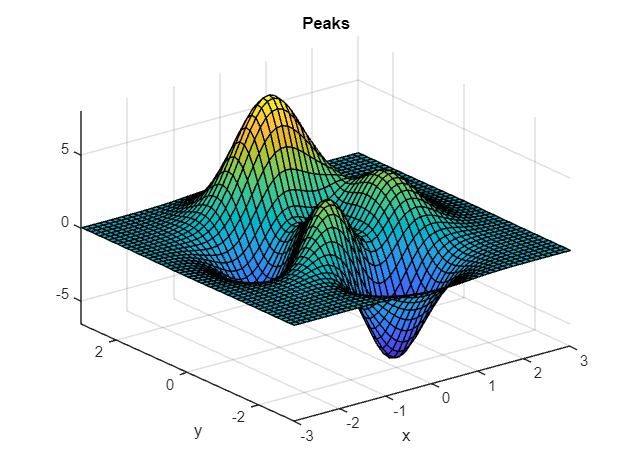

 
z =  3*(1-x).^2.*exp(-(x.^2) - (y+1).^2) ... 
   - 10*(x/5 - x.^3 - y.^5).*exp(-x.^2-y.^2) ... 
   - 1/3*exp(-(x+1).^2 - y.^2) 
 


        continue

    end
    Z = cConst.*Z;

  Name               Size            Bytes  Class    Attributes

  array_of_cell      2x3              1640  cell               



    % f = A(i+1) - обращение к другому элементу
    A(:,i) = svds(Z,n);

  Name            Size            Bytes  Class    Attributes

  empty_cell      0x0                 0  cell               



    % break- нельзя!

empty_cell = 1×1 cell array
    {[1]}


    % continue  - можно

  Name            Size            Bytes  Class    Attributes

  empty_cell      1x1               105  cell               



end
A
toc
tocBytes

array_of_cell = 2×3 cell array
    {'1'   }    {["2"       ]}    {[       3]}
    {@peaks}    {10×10 double}    {1×1 Figure}


wh = whos("A","cConst");

array_of_cell_of_cell = 2×1 cell array
    {2×3 cell}
    {2×3 cell}


sum(arrayfun(@(x)x.bytes,wh))*cur_pool.NumWorkers

array_of_cell_concat = 4×3 cell array
    {'1'   }    {["2"       ]}    {[       3]}
    {@peaks}    {10×10 double}    {1×1 Figure}
    {'1'   }    {["2"       ]}    {[       3]}
    {@peaks}    {10×10 double}    {1×1 Figure}


 
z =  3*(1-x).^2.*exp(-(x.^2) - (y+1).^2) ... 
   - 10*(x/5 - x.^3 - y.^5).*exp(-x.^2-y.^2) ... 
   - 1/3*exp(-(x+1).^2 - y.^2) 
 


cConst = randn(n,1);

A = zeros(n);
tic
for i=1:n
    Z = rand(n);

folder = 'D:\Program Files\matlab files\matlab-seminar\basics'

    if (norm(Z)/n) > 0.5

full_file = "D:\Program Files\matlab files\matlab-seminar\basics\tbl.xls"

        continue
    end
    Z = cConst.*Z;
    A(:,i) = svds(Z,n);
end

tbl1 = 21×6 cell array
    {'а'     }    {'ё'         }    {'а'     }    {'а'     }    {'и'     }    {'л'     }
    {[0.8678]}    {[    0.2793]}    {[0.6847]}    {[0.3079]}    {[0.5812]}    {[0.3905]}
    {[0.1935]}    {[    0.5229]}    {[0.4819]}    {[0.1671]}    {[0.1861]}    {[0.5763]}
    {[0.4268]}    {[    0.4919]}    {[0.3824]}    {[0.7220]}    {[0.3784]}    {[0.1908]}
    {[0.8727]}    {[    0.3974]}    {[0.5414]}    {[0.3530]}    {[0.5992]}    {[0.8386]}
    {[0.3939]}    {[    0.0528]}    {[0.8323]}    {[0.2276]}    {[0.5367]}    {[0.4734]}
    {[0.0259]}    {[    0.1007]}    {[0.1129]}    {[0.5548]}    {[0.6885]}    {[0.6865]}
    {[0.3905]}    {[    0.3607]}    {[0.3874]}    {[0.8483]}    {[0.0207]}    {[0.9123]}
    {[0.5539]}    {[    0.2077]}    {[0.0778]}    {[0.0565]}    {[0.9047]}    {[0.7128]}
    {[0.4428]}    {[    0.6165]}    {[0.1745]}    {[0.7798]}    {[0.2640]}    {[0.5166]}
    {[0.7391]}    {[    0.4836]}    {[0.2886]}    {[0.9381]}    {[0.8524]}    {[0.7508]

toc

 readcell Create a cell array by reading from a file.
 
    Use the readcell function to create a cell array by reading
    column-oriented data from a file. readcell can automatically determine
    the file format from its extension.
 
    C = readcell(FILENAME) creates a cell array by reading from a file.
    FILENAME can be one of these:
 
        - For local files, FILENAME can be an absolute path that contains
          a filename and file extension. FILENAME can also be a relative
          path to the current directory or to a directory on the MATLAB
          path. For example, to import a file on the MATLAB path:
 
             C = readcell("patients.xls");
 
        - For files from an Internet URL or stored at a remote location,
          FILENAME must be a full path using a Uniform Resource Locator
          (URL). For example, to import a remote file from Amazon S3,
          specify the full URL for the f

A

### Контейнеры (встроенные типы для хранения разнородных данных)

### тип cell

Для хранения разнотипных данных  в структуры с числовыми индексами

clearvars
array_of_cell = {'1',"2",3;@peaks,rand(10),figure(10)} % 
array_of_cell(1) % возращает тип cell
array_of_cell{1} % возвращает содержимое ячейки
array_of_cell{2,1}() % вызываем указатель на функцию, который хранится в ячейке
% array_of_cell(1){1} так нельзя
whos array_of_cell
empty_cell = {};
whos empty_cell
empty_cell{1} = true

struct_scalar = struct with fields:
          field1: [10×10 double]
          field2: 'Содержимое ячейки 2'
          field3: []
    peaks_handle: @peaks


whos empty_cell

ans =     0.7405    0.6787    0.2588    0.0252    0.6461    0.8063    0.1129    0.8055    0.2365    0.6957
    0.1131    0.2094    0.6352    0.4481    0.4847    0.9949    0.9847    0.4240    0.1915    0.9365
    0.3401    0.3024    0.1041    0.8576    0.9599    0.0415    0.1045    0.5410    0.3757    0.0303
    0.4272    0.6873    0.8195    0.3493    0.7006    0.9331    0.7417    0.7466    0.0666    0.7164
    0.6473    0.3637    0.6415    0.9284    0.8758    0.4422    0.4763    0.6818    0.4611    0.3622
    0.2272    0.0537    0.9123    0.3030    0.7620    0.8442    0.0894    0.4235    0.1158    0.3436
    0.6862    0.2953    0.4776    0.4420    0.4718    0.2487    0.5435    0.3116    0.3428    0.6905
    0.8237    0.9262    0.7312    0.5316    0.7761    0.6399    0.8929    0.1079    0.4718    0.7447
    0.3811    0.1917    0.1219    0.1404    0.1947    0.4578    0.5028    0.8287    0.4415    0.9213
    0.1748    0.8027    0.0095    0.2016    0.0962    0.6914    0.7941    0.6873    0

Массив ячеек

clearvars

names_of_fields = 4×1 cell array
    {'field1'      }
    {'field2'      }
    {'field3'      }
    {'peaks_handle'}


array_of_cell = {'1',"2",3;@peaks,rand(10),figure(10)} % 

ans = 'Содержимое ячейки 2'

 
z =  3*(1-x).^2.*exp(-(x.^2) - (y+1).^2) ... 
   - 10*(x/5 - x.^3 - y.^5).*exp(-x.^2-y.^2) ... 
   - 1/3*exp(-(x+1).^2 - y.^2) 
 


array_of_cell_of_cell = {array_of_cell;array_of_cell} % заворачивает cell в cell => массив ячеек массивов ячеек

array_of_cell_concat = [array_of_cell;array_of_cell] % матрица ячеек
array_of_cell_concat{2,1}() % - вызываем содержимое ячейки (а там - указатель на функцию peaks)


clearvars

struct_scalar = struct with fields:
          field1: 0.6563
          field2: 'Содержимое ячейки 2'
          field3: []
    peaks_handle: @peaks


folder = get_folder()

struct_array_empty = 1×10 struct array with fields:
    field1
    field2
    field3
    peaks_handle


full_file = fullfile(folder,"tbl.xls")
cell_1 = cell(21,6);

struct_array_filled = 1×10 struct array with fields:
    field1
    field2
    field3
    peaks_handle


cell_1(2:end,:) = num2cell(rand([20 6]));

ans = logical
   0


cell_1(1,:) = {"а" "ё" "а" "а" "и" "л" };

struct_array_filled = 1×10 struct array with fields:
    field1
    field2
    field3
    peaks_handle
    field4


writecell(cell_1,full_file);
tbl1 = readcell(full_file)
help("readcell")

a = 1

Пример  использования "cell"    - splat аргументов функции

% Пример  - splat аргументов функции

a =      1     1     1     1     1     1     1     1     1     1


A = rand(1,5);

a =     1.0000    0.6563    0.6563    0.6563    0.6563    0.6563    0.6563    0.6563    0.6563    0.2284


varar_fun(A(:))
C = num2cell(A);
varar_fun(C{:})

arg1
первый аргумент
arg2
    3.1416



arg1
     1

arg2
    0.6563

arg3
    0.6563

arg4
    0.6563

arg5
    0.6563

arg6
    0.6563

arg7
    0.6563

arg8
    0.6563

arg9
    0.6563

arg10
    0.2284



#### тип struct

Для хранения разнородных данных по имени

clearvars
struct_scalar = struct("field1",rand(10),"field2",'Содержимое ячейки 2',"field3",[], "peaks_handle",@peaks) % стурктура с полями
struct_scalar.field1 % получение данных из поля по названию поля
names_of_fields = fieldnames(struct_scalar) % возвращает имена полей
struct_scalar.(names_of_fields{2}) % имена можно задавать в виде символов,но это несколько медленнее
struct_scalar.peaks_handle()

Массив структур

clearvars
struct_scalar = struct("field1",rand(),"field2",'Содержимое ячейки 2',"field3",[], "peaks_handle",@peaks) % стурктура с полями

Name_Values_cell = 1×50 cell array
    {'a'}    {0×0 double}    {'b'}    {0×0 double}    {'c'}    {0×0 double}    {'d'}    {0×0 double}    {'e'}    {0×0 double}    {'f'}    {0×0 double}    {'g'}    {0×0 double}    {'h'}    {0×0 double}    {'i'}    {0×0 double}    {'j'}    {0×0 double}    {'k'}    {0×0 double}    {'l'}    {0×0 double}    {'m'}    {0×0 double}    {'n'}    {0×0 double}    {'o'}    {0×0 double}    {'p'}    {0×0 double}    {'q'}    {0×0 double}    {'r'}    {0×0 double}    {'s'}    {0×0 double}    {'t'}    {0×0 double}    {'u'}    {0×0 double}    {'v'}    {0×0 double}    {'w'}    {0×0 double}    {'x'}    {0×0 double}    {'y'}    {0×0 double}


struct_array_empty(10) = struct_scalar % резервирование памяти путем обратного индексирования  - для структур довольно удобно
% так как массив структур имеет все те же имена полей 
struct_array_filled(10:-1:1) = struct_scalar

Name_Values_cell = 1×50 cell array
    {'a'}    {[1]}    {'b'}    {[2]}    {'c'}    {[3]}    {'d'}    {[4]}    {'e'}    {[5]}    {'f'}    {[6]}    {'g'}    {[7]}    {'h'}    {[8]}    {'i'}    {[9]}    {'j'}    {[10]}    {'k'}    {[11]}    {'l'}    {[12]}    {'m'}    {[13]}    {'n'}    {[14]}    {'o'}    {[15]}    {'p'}    {[16]}    {'q'}    {[17]}    {'r'}    {[18]}    {'s'}    {[19]}    {'t'}    {[20]}    {'u'}    {[21]}    {'v'}    {[22]}    {'w'}    {[23]}    {'x'}    {[24]}    {'y'}    {[25]}


isfield(struct_scalar,"a")

st = struct with fields:
    a: 1
    b: 2
    c: 3
    d: 4
    e: 5
    f: 6
    g: 7
    h: 8
    i: 9
    j: 10
    k: 11
    l: 12
    m: 13
    n: 14
    o: 15
    p: 16
    q: 17
    r: 18
    s: 19
    t: 20
    u: 21
    v: 22
    w: 23
    x: 24
    y: 25


struct_array_filled(3).field4 = "f" % новое поле добавилось ко всем элементам 
struct_array_filled(end).field1=rand();
struct_array_filled(1).field1=1;

ans = 25

a = struct_array_filled(:).field1 % возвращает первый элемент
a(10:-1:1)=struct_array_filled(:).field1 % тут не получилось
a= [struct_array_filled(:).field1] % list comprehention

% varar_fun - показывает свои аргументы по одному
varar_fun("первый аргумент", pi)

folder = 'D:\Program Files\matlab files\matlab-seminar\basics'

varar_fun(struct_array_filled(:).field1)  % можно использовать аналогично {:} для передачи большого числа аргументов по одному (splat -функция)

full_file = "D:\Program Files\matlab files\matlab-seminar\basics\tbl.xls"

# Выводы по семинару 3.

- Если есть "parallel computing toolbox", то можно распараллеливать вычисления при помощи **parfor...continue....end. **Основной принцип расботы с параллельными циклами - нобходимо помнить, что итерации цикла выполняются независимо друг от друга и нельзя чтобы в коде цикла могла возникнуть ситуация, когда параллельные процессы конкурируют за один и тот же элемент массива

- Для хранения разнотипных данных в объектах с индексированием по типу массивов можно пользоваться массивом ячеек, тип **cell, **для которого существуют два способа индексирования (i,j) - возвращает элемент массива с типом **cell**, {i,j} - вытаскивает содержимое ячейки. Индексирование с круглыми скобками позволяет делать все те же операции с массивом ячеек, что и с массивом чисел.

- Тип **cell **используется для передаче функции произвольного числа аргументов, для передачи аргументов по одному можно использовать **splat** - функцию **{:}**

- Тип **struct** - для хранения разнотипных данных в массиве с "индексированием" при помощи имени. Может также использоваться для передаче большого числа аргументом по одному 

# Семинар 4. Контейнеры для работы с разнотипными данными

- Таблицы

- Множества

- Словари

- Использование контейнеров java

Небольшой пример по использованию структур и функции **{:}** из предыдущего семинара 

Конструктор объекта типа **struct **имеет следующую форму:

**struct("field1_name",value1,...."fieldN_name",valueN)**

Для конструкирования структуры с заданными именами полей можно использовать возможности "splat" - функции ячеек.

Для примера создадим стурктуру с именами полей от 'a' до 'y' и значениями  в этих полях от 1 до 25

clearvars
field_names = arrayfun(@string,'a':'y');
n = numel(field_names);
Name_Values_cell = cell(1,2*n); % создаем пустой массив ячеек, 

% в него будут поочередно добавлены имена полей и их значения

% заплоняем имена полей

 readtable Create a table by reading from a file.
 
    Use the readtable function to create a table by reading column-oriented
    data from a file. readtable automatically determines the file format
    from its extension as described below.
 
    T = readtable(FILENAME) creates a table by reading from a file, where
    FILENAME can be one of these:
 
        - For local files, FILENAME can be a full path that contains
          a filename and file extension. FILENAME can also be a relative
          path to the current folder, or to a folder on the MATLAB path.
          For example, to import a file on the MATLAB path:
 
             T = readtable("patients.xls");
 
        - For files from an Internet URL or stored at a remote location,
          FILENAME must be a full path using a Uniform Resource Locator
          (URL). For example, to import a remote file from Amazon S3,
          specify the full URL for the

Name_Values_cell(1:2:end) = cellstr(field_names); % cellstr - преобразует массив string в ячейку массивов char
Name_Values_cell
% заполняем содержимое ячеек

Methods for class table:

abs           acos          acosd         acosh         acot          acotd         acoth         acsc          acscd         acsch         addprop       addvars       and           asec          asecd         asech         asin          asind         asinh         atan          atan2         atan2d        atand         atanh         cat           ceil          convertvars   cos           cosd          cosh          cospi         cot           cotd          coth          csc           cscd          csch          cummax        cummin        cumprod       cumsum        diff          eq            exp           expm1         fix           floor         ge            gt            horzcat       inner2outer   innerjoin     intersect     isempty       ismember      isprop        issortedrows  istable       istabular     join          keyHash       keyMatch      ldivide       le            log           log10         log1p         log2          lt            max     

Name_Values_cell(2:2:end) = num2cell(1:n); %
Name_Values_cell

tbl1 = 20×6 table
     name         a1         a2         a3          a4          a5   
    _______    ________    _______    _______    ________    ________

    0.81472     0.65574    0.43874    0.75127     0.35166     0.16218
    0.90579    0.035712    0.38156     0.2551     0.83083     0.79428
    0.12699     0.84913    0.76552    0.50596     0.58526     0.31122
    0.91338     0.93399     0.7952    0.69908     0.54972     0.52853
    0.63236     0.67874    0.18687     0.8909     0.91719     0.16565
    0.09754     0.75774    0.48976    0.95929     0.28584     0.60198
     0.2785     0.74313    0.44559    0.54722      0.7572     0.26297
    0.54688     0.39223    0.64631    0.13862     0.75373     0.65408
    0.95751     0.65548    0.70936    0.14929     0.38045     0.68921
    0.9

st = struct(Name_Values_cell{:}) % конструктор структур поддерживает произвольное число аргументов


mean_val = 1×5 table
      a1         a2         a3         a4         a5   
    _______    _______    _______    _______    _______

    0.49256    0.50568    0.50617    0.49353    0.48142


standard_deviation = 1×5 table
      a1         a2         a3         a4         a5   
    _______    _______    _______    _______    _______

    0.33447    0.23973    0.28621    0.28684    0.29069


Variables:

    name: 20×1 double

        Properties:
            Description:  а
        Values:

            Min       0.09754 
            Median    0.79624 
            Max       0.97059 

    a1: 20×1 double

        Properties:
            Description:  ё
        Values:

            Min       0.031833
            Median     0.65561
            Max        0.95022

    a2: 20×1 double

        Properties:
            Description:  а
        Values:

            Min         0.119 
            Median    0.49406 
            Max       0.95974 

    a3: 20×1 double

        Properties:
            Description:  а
        Values:

            Min       0.13862 
            Median    0.48962 
            Max       0.95929 

    a4: 20×1 double

        Properties:
            Description:  и
        Values:

            Min       0.011902
            Median     0.54026
            Max        0.93401

 

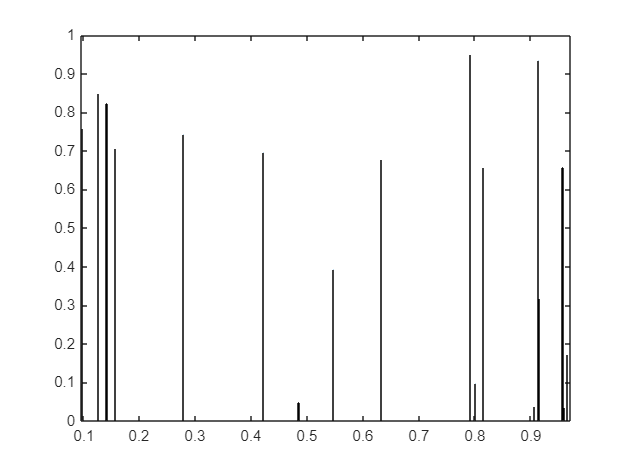

st.y

#### тип table

Для хранения данных в табличках с именами столбцов

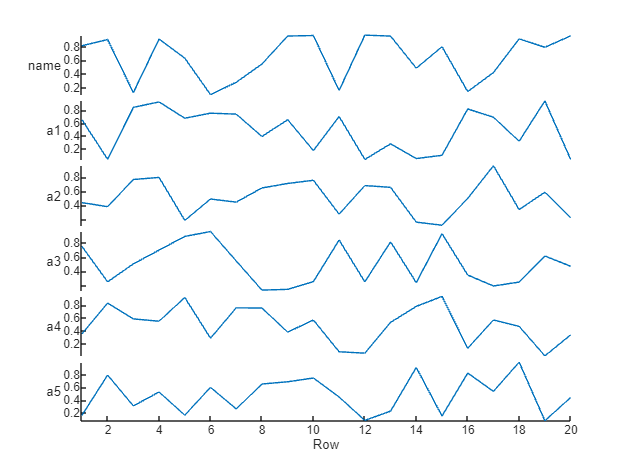

clearvars

folder = get_folder()
full_file = fullfile(folder,"tbl.xls")
cell_1 = cell(21,6);
cell_1(2:end,:) = num2cell(rand([20 6]));
cell_1(1,:) = {"а" "ё" "а" "а" "и" "л" };
writecell(cell_1,full_file);
tbl1 = readtable(full_file); 
% можно читать таблички из эксель или текстовых файлов с разделителем, например, .csv
% readtable - высокоуровневая читалка с очень большим набором функций
help("readtable")

% функции, которые работают с объектами типа таблица
methods(tbl1)

tbl1.Properties.VariableNames = {'name' 'a1' 'a2' 'a3' 'a4' 'a5'}


d =

  dictionary (string ⟼ cell) with 3 entries:

    "sin" ⟼ {@sin}
    "cos" ⟼ {@cos}
    "tan" ⟼ {@tan}



mean_val = mean(tbl1(:,2:end)) % среднее значение 

ans = 1×1 cell array
    {@sin}


standard_deviation=std(tbl1(:,2:end)) % среднее значение 

d1 = 1×1 cell array
    {@sin}


summary(tbl1)

ans = 1.2246e-16

bar(tbl1.name,tbl1.a1)


d =

  dictionary (string ⟼ cell) with 4 entries:

    "sin" ⟼ {@sin}
    "cos" ⟼ {@cos}
    "tan" ⟼ {@tan}
    "cot" ⟼ {@cot}



stackedplot(tbl1)

Error using  {} 
Key not found.

%tbl2 = table([1:4]',ones(4,3,2),eye(4,2))  - элементы разной размерности
%работают но не отображаюстя в LiveScript


#### тип containers.Map

Для хранения разнородных данных по имени (ключу)

clearvars
M = containers.Map('KeyType','char','ValueType','double')
M("a")=10
methods(M)

#### тип dictionary (рекомендуется вместо containers.Map)

Для хранения и получения данных по "ключу"

clearvars
d =  dictionary(["sin" "cos" "tan"],{@sin, @cos, @tan})
d("sin")
d1 = d("sin")
d1{1}(pi)
d("cot") = {@cot}

d2 = dictionary({[false true true] [true false true] [true true false]},{@sin, @cos, @tan}) 
% можно в качестве ключей использовать массивы
fun = d2({[true true false]})
fun{1}(pi)

#### Итерирование по коллекциям

Циклы могут перебирать элементы коллекций (но только родных джавовских не могут)

% итерирование по ячейкам
A_cell = {1,2,3}
for a = A_cell
    class(a)
    disp(a{1})
end


% итерирование по структурам
A_struct(3) = struct('f1',3);
A_struct(1).f1 = 1;A_struct(2).f1 = 2;

for st = A_struct
    disp("st(i)=" + st.f1)
end

%итерирование по словарям

A_dict = dictionary(["a" "b" "c"],[1 2 3])
try
    for d = A_dict
        d
    end
catch Ex
    "ss"
end
i = 0;

ans = 1×2 string array
    "b"    "c"


for key = keys(A_dict)'

ans = 1×2 string array
    "c"    "b"


    i = i+1

ans = "a"

    disp("key => value:  " + key+"=>"+ A_dict(key))

ans = 1×3 string array
    "a"    "b"    "c"


end
A_dict(key)

## Не хватает коллекции уникальных элементов типа множество

#### Вариант 1 методы матлаб для работы с массивами как с множествами:

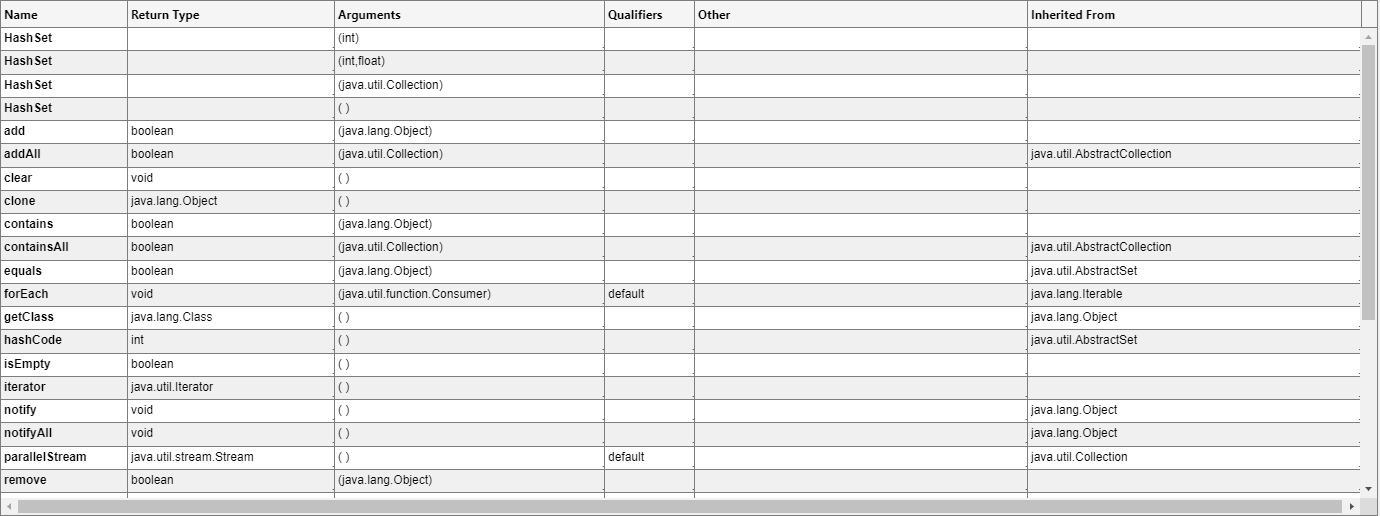

clearvars

A = ["c"  "b" "a" "c"];
B = ["a" "d"];
setdiff(A,B) % Элементы множества A не содержащиеся в множестве B
setdiff(A,B,'stable') % чтобы сохранить изначальный порядок элементов в массиве
intersect(A,B) % Пересечение двух множеств
unique(A)

Methods for class java.util.HashSet:

HashSet         add             addAll          clear           clone           contains        containsAll     equals          forEach         getClass        hashCode        isEmpty         iterator        notify          notifyAll       parallelStream  remove          removeAll       removeIf        retainAll       size            spliterator     stream          toArray         toString        wait            



#### Вариант 2: использовать богатый арсенал java ( collections)

Матлаб имеет "встроенный" java 8

methodsview(java.util.HashSet) % Графическая оболочка для java документации

Пример нахождения пересечения двух множеств

import java.util.HashSet % java.util.* - импортирует все коллекции из джавы 
jA = HashSet; % вызываем конструктор для джава объекта
jB = HashSet; % вызываем конструктор для джава объекта
methods(jA)


ans = logical
   1


ans = logical
   1


ans = logical
   1


A = ["a" "b" "c"];
B = ["a" "d"];


ans = logical
   1


ans = logical
   1


for iii = A


unionAB =

[a, b, c]



    add(jA,iii) % добавляем элемент в множество jA

ans = logical
   1


end
for iii = B


jA =

[a, b, c]



    add(jB,iii) % добавляем элемент в множество jB


unionAB =

[a, b, c, d]



end
unionAB = clone(jA) % клонирует объект (метод java)


intersectionAB =

[a, b, c]



unionAB.addAll(jB) % функция добавляет элементы множества jB в множество  unionAB

ans = logical
   1



jA


jA =

[a, b, c]



unionAB


intersectionAB =

[a]




intersectionAB = clone(jA)
intersectionAB.retainAll(jB)

jA
intersectionAB


Вместо типа dictionary можно использовать java.util.HashMap, это возможно будет работать быстрей (скорее всего) 

methodsview(java.util.HashMap)

import java.util.HashMap % можно использовать вместо словарей

Methods for class java.util.HashMap:

HashMap           clear             clone             compute           computeIfAbsent   computeIfPresent  containsKey       containsValue     entrySet          equals            forEach           get               getClass          getOrDefault      hashCode          isEmpty           keySet            merge             notify            notifyAll         put               putAll            putIfAbsent       remove            replace           replaceAll        size              toString          values            wait              



jMap = java.util.HashMap; % создается объект java с которым напрямую можно работать из матлаб 
methods(jMap)
jMap.put("a",figure(1));


ans =

[a, b]



jMap.put("b",figure(2));

ans =   Figure (2) with properties:

      Number: 2
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [488 242 560 420]
       Units: 'pixels'

  Show all properties


keySet(jMap)


jMap =

{a=matlab.ui.Figure, b=matlab.ui.Figure}



jMap.get("b") % вытакскиваем число


jArrayObj =

  java.lang.Object[]:

    [matlab_ui_FigureBeanAdapter0]
    [matlab_ui_FigureBeanAdapter0]



jMap

Methods for class java.lang.Object[]:

equals     getClass   hashCode   notify     notifyAll  toString   wait       



jArrayObj = jMap.values().toArray()
methods(jArrayObj)

ans =   Figure (1) with properties:

      Number: 1
        Name: ''
       Color: [1 1 1]
    Position: [488 242 560 420]
       Units: 'pixels'

  Show all properties


ans = "asdf"

f_array= arrayfun(@(i)jArrayObj(i), 1:jMap.size(),"UniformOutput",false);
f_array{1}

function return_value = like_example(be_like_me)
    return_value = zeros(numel(be_like_me),'like',be_like_me);
    return_value = return_value*be_like_me(:);
end
function A = fill_by_row()
    N = 5000;
    A = zeros(N);
    for iii=1:N % внешний цикл перебирает строки
        for jjj=1:N
            A(iii,jjj) = 5;
        end
    end
end
function A = fill_by_column()
    N = 5000;
    A = zeros(N);
    for jjj=1:N % внешний цикл перебирает колонки
        for iii=1:N
            A(iii,jjj) = 5;
        end
    end
end
function A=fill_by_column_no_memalloc()
    N = 5000;
    for jjj=1:N % внешний цикл перебирает колонки
        for iii=1:N
            A(iii,jjj) = 5;
        end
    end    
end
function MAT=fill_by_column_reverse_order()
    N = 5000;
    for jjj=N:-1:1 % внешний цикл перебирает колонки
        for iii=N:-1:1
            MAT(iii,jjj) = 5;
        end
    end    
end

function [r_str,r_ch] = gen_random_string(N)
        alfabeth = 'a':'y';
        n = numel(alfabeth);
        rand_inds = randi(n,[1,N]);
        r_ch = alfabeth(rand_inds);
        r_str = string(r_ch);
end

%% Сравнение операций, выполняемых непосредственно для всей матрицы и перебором элементов матрицы
function A = sin_in_circle(A)
    N = size(A);
    for jjj=1:N(2) % внешний цикл перебирает колонки
        for iii=1:N(1)
            A(iii,jjj) = sin(A(iii,jjj));
        end
    end
end
function A = sin_direct(A)
    A = sin(A);
end
function A = sin_in_circle_line_index(A)
    N = numel(A);
    for iii=1:N
        A(iii) = sin(A(iii));
    end
end
%
function out = ALL(A)
    out = sum(A,'all');
end
% что быстрей итерирование по коллекции или итерирование с индексацией
function s = indexwise_iter() % индексирование по индексам
    A = rand(100000,1);
    s=0;
    for iii = 1:numel(A)
        s = s+ A(iii);
    end
end
function s = elementwise_iter()
    A = rand(100000,1);
    s=0;
    for a = transpose(A)
        s = s+ a;
    end
end
% Пример исопльзования структур типа cell  - функция с произвольным числом
% аргументов
function varar_fun(varargin)
    counter = 0;
    for arg = varargin
        counter = counter + 1;
        disp("arg" + counter);
        disp(arg{1})
    end
end

function folder = get_folder()
% текущая папка
folder = fileparts(matlab.desktop.editor.getActiveFilename);
end